## DTFT Demo

filename: DTFT_Demo.mlx

Last Update: 11-16-23

This file shows how an averaging filter will look for different values of Sigma on the complex plane and how that corresponds to the graph.

## 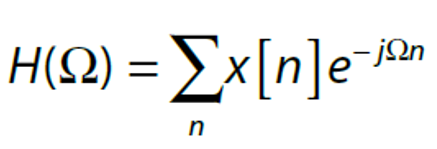

clear;
close all;
omega= 0.4*pi;
filter_length=10;
hn=ones(filter_length,1)*1/filter_length %construct the discrete time averaging filter

hn =     0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000


H_omega_terms=complex(zeros(filter_length,1)); %preallocates memory for Homega terms
for i=1:filter_length
    H_omega_terms(i)=1/filter_length*exp(-1i*(i-1)*omega);
end
H_omega_terms

H_omega_terms =    0.1000 + 0.0000i
   0.0309 - 0.0951i
  -0.0809 - 0.0588i
  -0.0809 + 0.0588i
   0.0309 + 0.0951i
   0.1000 + 0.0000i
   0.0309 - 0.0951i
  -0.0809 - 0.0588i
  -0.0809 + 0.0588i
   0.0309 + 0.0951i


H_omega_total=sum(H_omega_terms)

H_omega_total = -5.2042e-17 + 1.3878e-17i

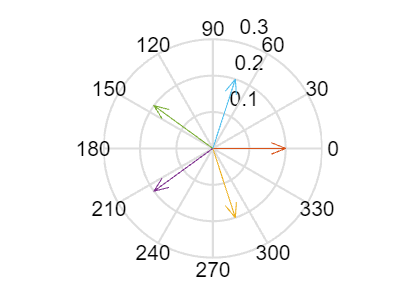

invisible = 0.3; %just used to set limit
%create the visual representation including labels
invis_Figure=compass(invisible,0);
hold on;
for i=1:length(H_omega_terms)
    compass(H_omega_terms(i))
end
compass(H_omega_total,'k')

%legend(["","1","c2"])
set(invis_Figure,"Visible","off");
hold off;

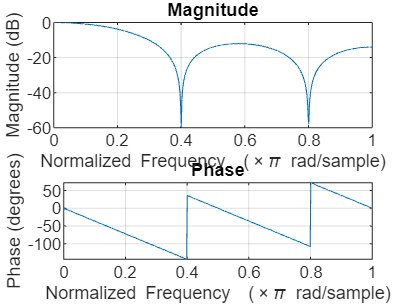

freqz(hn)